clc
clear
close all

% Define Laplace variable
s = tf('s');

% Define transfer functions
G1 = 1/(s+1);
G2 = 5/(s+2);
H  = 2/(s+3);

% Series combination
G = series(G1,G2);

% Closed loop system
T = feedback(G,H);

% Display result
disp('Closed Loop Transfer Function:')

Closed Loop Transfer Function:


T


T =
 
         5 s + 15
  -----------------------
  s^3 + 6 s^2 + 11 s + 16
 
Continuous-time transfer function.


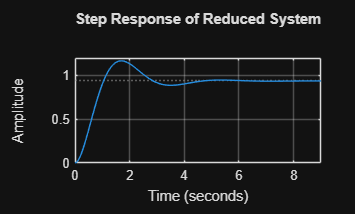


% Step response
figure
step(T)
title('Step Response of Reduced System')
grid on

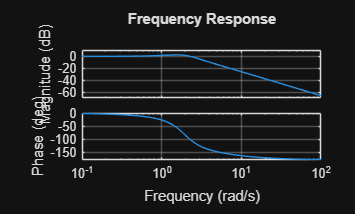


% Bode plot
figure
bode(T)
grid on
title('Frequency Response')

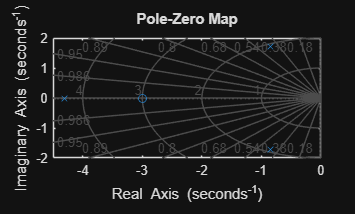


% Pole-zero map
figure
pzmap(T)
grid on
title('Pole-Zero Map')

sys1 = tf(1,[1 1])


sys1 =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.


sys2 = tf(5,[1 2])


sys2 =
 
    5
  -----
  s + 2
 
Continuous-time transfer function.


sys3 = tf(2,[1 3])


sys3 =
 
    2
  -----
  s + 3
 
Continuous-time transfer function.



sys = feedback(series(sys1,sys2),sys3)


sys =
 
         5 s + 15
  -----------------------
  s^3 + 6 s^2 + 11 s + 16
 
Continuous-time transfer function.
